# Milling and Welding Todo

**Team members:**

Javier Cabrera

Julia Gasull

**Link: **[https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same pose during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º among the two cylinder axis

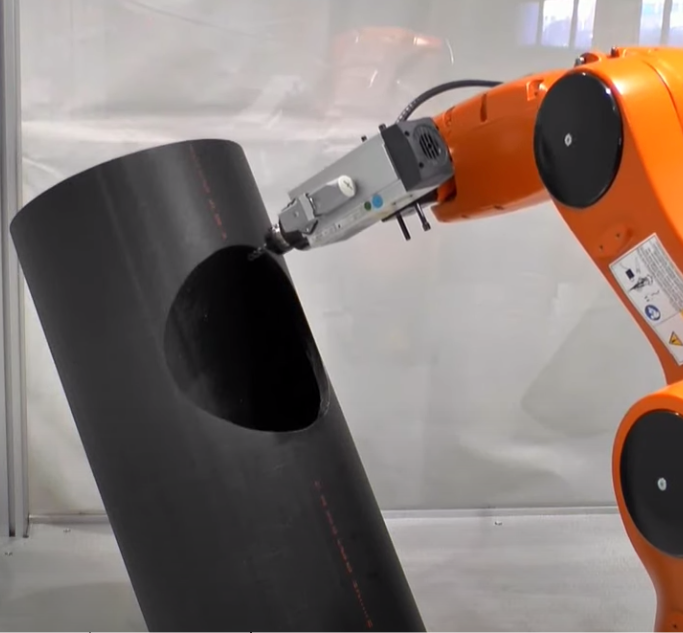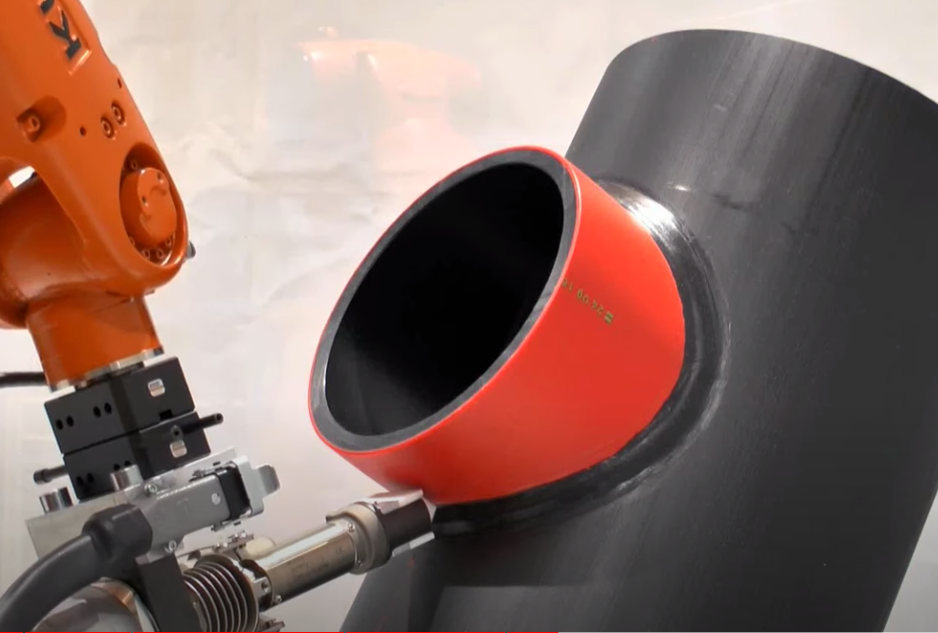

## Sketching your ideas

Conceptualize the problem. Add a sketch and make some small scripts

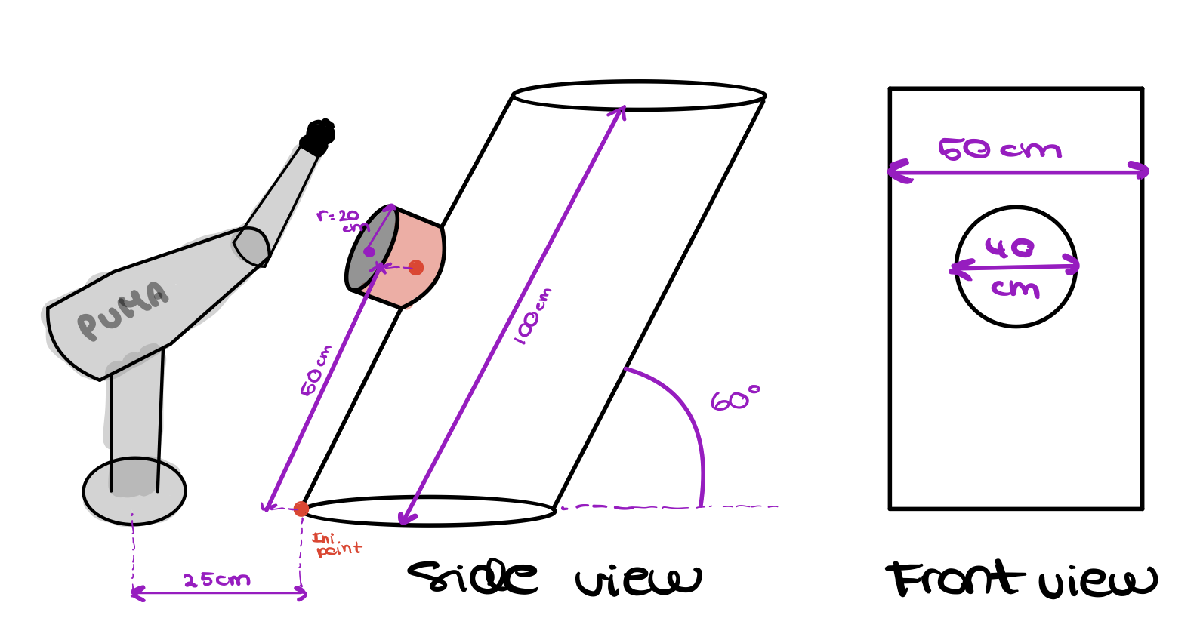

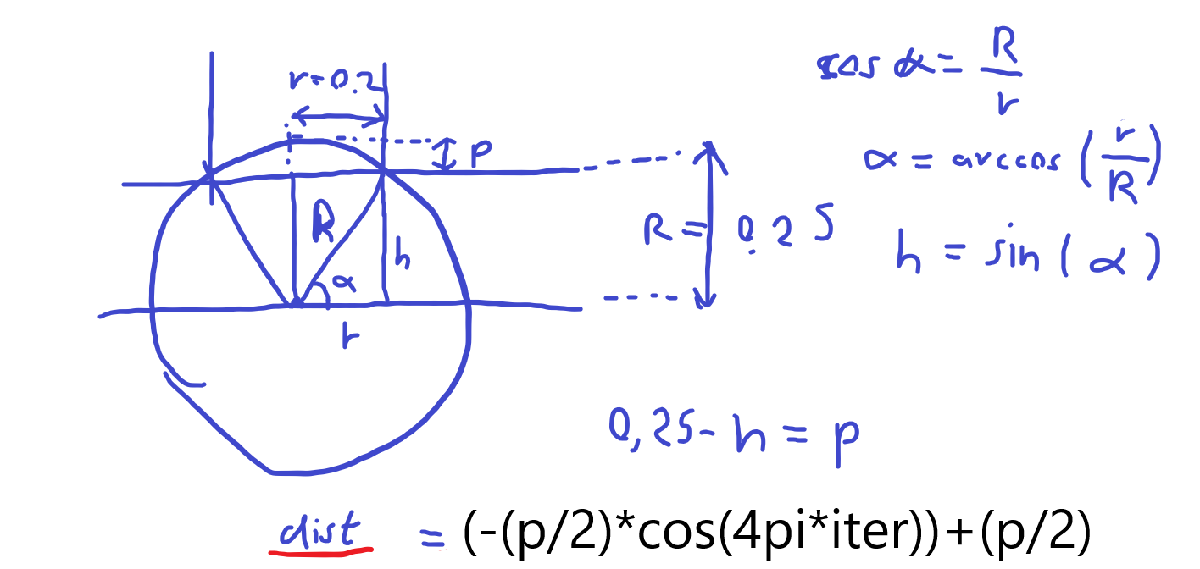

## Parte 1 - Drill

Primero calcularemos el agujero hecho con el taladro.

### Calculo del punto central del circulo

En base a la información que tenemos del sketch, calculamos el punto central del circulo  a taladrar.

clc;
clear;
close all;
radius = 0.20; % 20 cm

INI_POINT = [0.25; 0; 0]

INI_POINT =     0.2500
         0
         0


dist_from_ini = 0.4 % 1 meter

dist_from_ini = 0.4000

CENTER_CIRCLE = INI_POINT+[dist_from_ini*cos(pi/3); 0; dist_from_ini*sin(pi/3)]

CENTER_CIRCLE =     0.4500
         0
    0.3464


### Calculo de la rotación

n = 200; % Number of iterations
INI_ROBOT = transl(CENTER_CIRCLE(1), CENTER_CIRCLE(2), CENTER_CIRCLE(3));

Unrecognized function or variable 'transl'.


big_radius = 0.25
angle_of_joint = acos(radius/big_radius);
height_of_joint = big_radius*sin(angle_of_joint)
profundity = (big_radius - height_of_joint)/2

for i=1:n
 Laser_Pose(:,:,i)= INI_ROBOT*troty(2*pi/3)* ...
     transl(0, 0, (-profundity*cos(4*pi*i/n))+profundity)* ...
     trotz(2*pi*i/n)*transl(-radius, 0, 0) ...
 ;
end

### Plot de trazado resultante y puntos de referencia

mdl_puma560
Q = p560.ikine6s(Laser_Pose, 'run');
p560.plot(Q,'trail','-','view',[-170 10], 'zoom',1.5,'workspace', [-0.5 1 -0.5 0.5 -1 1])

hold on;
plot3(INI_POINT(1), INI_POINT(2), INI_POINT(3),'-go');
plot3(CENTER_CIRCLE(1), CENTER_CIRCLE(2), CENTER_CIRCLE(3),'-ro');
hold off;

## Parte 2 - Soldar

Una vez calculado el taladro, la siguiente parte es soldar una vez colocada la tuberia. Para ello deberemos soldar a 45º.

clc;
close all;
radius=0.20; % 20 cm

INI_POINT = [0.25; 0; 0]
dist_from_ini = 0.4 % 1 meter
CENTER_CIRCLE = INI_POINT+[dist_from_ini*cos(pi/3); 0; dist_from_ini*sin(pi/3)]

### Calculo de la rotación

A diferencia del taladro, ahora el robot debe soldar a 45º.

n=200; % Number of iterations
INI_ROBOT = transl(CENTER_CIRCLE(1), CENTER_CIRCLE(2), CENTER_CIRCLE(3));

big_radius = 0.25
angle_of_joint = acos(radius/big_radius);
height_of_joint = big_radius*sin(angle_of_joint)
profundity = (big_radius - height_of_joint)/2

for i=1:n
    Laser_Pose(:,:,i)= INI_ROBOT*troty(2*pi/3)* ...
        transl(0, 0, (-profundity*cos(4*pi*i/n))+profundity)* ...
        trotz(2*pi*i/n)*transl(-radius, 0, 0)*troty(pi/4) ...
    ;
end

### Plot de trazado resultante y puntos de referencia

mdl_puma560
Q = p560.ikine6s(Laser_Pose, 'run');
p560.plot(Q,'trail','-','view',[-170 10], 'zoom',1.5,'workspace', [-0.5 1 -0.5 0.5 -1 1])

hold on;
plot3(INI_POINT(1), INI_POINT(2), INI_POINT(3),'-go');
plot3(CENTER_CIRCLE(1), CENTER_CIRCLE(2), CENTER_CIRCLE(3),'-ro');
hold off;